# Optimización unidimensional usando aproximación de tipo bisección en MATLAB

**Alumno:** Pablo Ruiz Molina

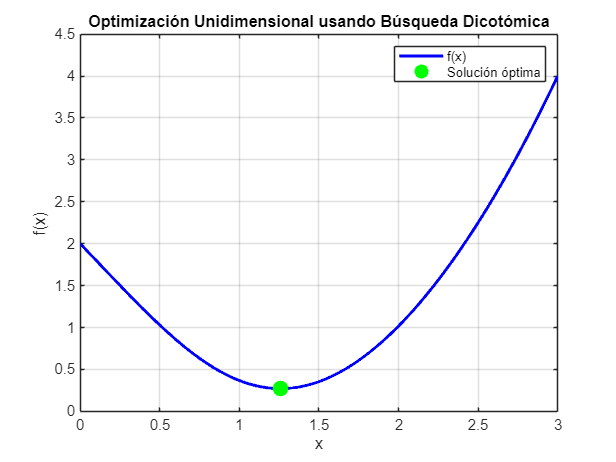

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda dicotómica
delta = 1e-6;  % Tolerancia (delta)

% Inicialización de las variables
max_iter = 100;  % Número máximo de iteraciones

% Obtener la solución óptima final
[f_opt, x_opt, iter] = bisec(f, a, b, delta, max_iter);


% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);

figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
legend('f(x)');
hold on;
% Marcar la solución óptima en el gráfico
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;
hold off;

% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720



## Anexo

function [f_opt, x_opt, iter] = bisec(f, a, b, delta, max_iter)
    % MÉTODO DE BISECCIÓN PARA ENCONTRAR UN MÍNIMO LOCAL
    % Buscamos el cero de la derivada f'(x), es decir, un extremo local.
    %
    % Entradas:
    %   f        - Función objetivo (debe ser diferenciable en [a, b])
    %   a, b     - Extremos iniciales del intervalo [a, b]
    %   tol      - Tolerancia para la convergencia
    %   max_iter - Número máximo de iteraciones permitidas
    %
    % Salidas:
    %   f_opt: valor de la función dónde se alcanza el óptimo 
    %   x_opt    - Aproximación del punto donde f'(x) = 0 (mínimo o máximo)
    %   iter     - Número de iteraciones realizadas

    % Paso 1: Derivar la función numéricamente
    syms x
    df = matlabFunction(diff(f, x));

    % Paso 2: Verificar que f'(a) y f'(b) tengan signos opuestos
    if df(a) * df(b) > 0
        error('El intervalo [a, b] no garantiza un cambio de signo en f''(x).');
    end

    % Inicialización iteraciones
    iter = 0;
    
    % Paso 3: Proceso iterativo de bisección
    while (b - a) / 2 > delta && iter < max_iter
        iter = iter + 1;
        
        % Paso 4: Calcular el punto medio
        x_mid = (a + b) / 2;
        df_mid = df(x_mid);
        
        % Paso 5: Verificar si f'(x_mid) ≈ 0
        if abs(df_mid) < delta
            x_opt = x_mid;
            f_opt = f(x_opt);
            return;
        end
        
        % Paso 6: Actualizar el intervalo según el signo de la derivada
        if df(a) * df_mid < 0
            b = x_mid; % La raíz de f'(x) está en [a, x_mid]
        else
            a = x_mid; % La raíz de f'(x) está en [x_mid, b]
        end
    end
    
    % Paso 7: Cálculo del mínimo
    x_opt = (a + b) / 2;
    f_opt = f(x_opt);
end
